**Exercise 1:  ** 

Let f(x) = ex - 1 and g(x) = 1 - x2 for x ∈ [0; 1]. Draw the graphs of the two functions f and g, determine the point of intersection z of the two graphs and calculate the area of the region between the two graphs in [0; z].   

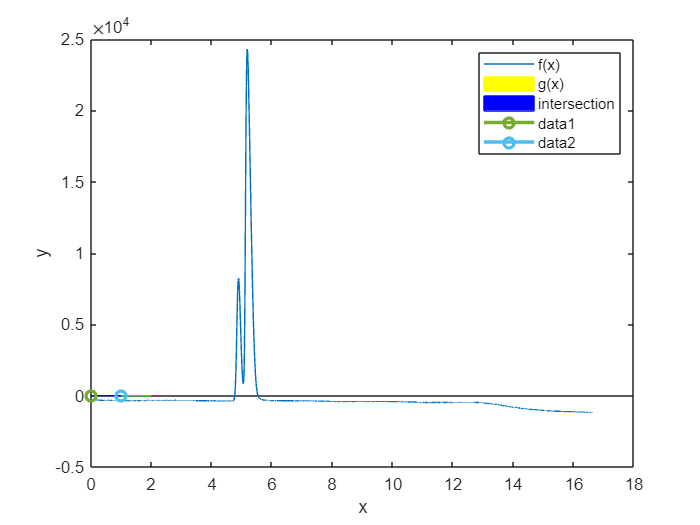


x = 0:1;


f= exp(x)-1;
g = 1- x.^2;

p = intersect(f,g);


area(x,f,"EdgeColor","yellow","FaceColor","yellow")
hold on
area(x,g,"EdgeColor","blue","FaceColor","blue")
area(x,p,"EdgeColor","green","FaceColor","green")

xlabel('x')
ylabel('y')
legend('f(x)', 'g(x)','intersection')

plot(x,p,Marker="O",LineWidth=2)

hold off



**Exercise 2: ** 

 Briefly describe probability distributions with continuous random variables (Uniform distribution) The, Compare the “ probability density function” and the “Continuous uniform cumulative distribution function” of the following continuous uniform random variables: X1 ~ U(0, 1), X2 ~ U(-3, 2), X3 ~ U(2, 4), X4 ~ U(0.8, 1.5 Next, determine the the mean and variance values for the continuous uniform distribution.  


X = randi([0 50],5,1)

X =     17
    10
    12
    31
    24


x1 = randi([0,1],5,1);
x2 = randi([-3,2],5,1);
x3 = randi([2,4],5,1);
s = [0.8,1.5];
x4 = rand(5,1)*diff(s)+s(1);


pd = fitdist(X,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu =    18.8   [7.99681, 29.6032]
    sigma = 8.70057   [5.2128, 25.0016]


cdfX = normcdf(X,mean(X),std(X))

cdfX =     0.4181
    0.1559
    0.2172
    0.9196
    0.7250



pd1 = fitdist(x1,'Normal')

pd1 =   NormalDistribution

  Normal distribution
       mu =      0.8   [0.244711, 1.35529]
    sigma = 0.447214   [0.26794, 1.28509]


cdfX1 = normcdf(x1,mean(x1),std(x1))

cdfX1 =     0.0368
    0.6726
    0.6726
    0.6726
    0.6726



pd2 = fitdist(x2,'Normal')

pd2 =   NormalDistribution

  Normal distribution
       mu =    -0.2   [-1.81893, 1.41893]
    sigma = 1.30384   [0.781174, 3.74666]


cdfX2 = normcdf(x2,mean(x2),std(x2))

cdfX2 =     0.0837
    0.8213
    0.8213
    0.2697
    0.5610



pd3 = fitdist(x3,'Normal')

pd3 =   NormalDistribution

  Normal distribution
       mu = 3   [1.75834, 4.24166]
    sigma = 1   [0.599133, 2.87356]


cdfX3 = normcdf(x3,mean(x3),std(x3))

cdfX3 =     0.1587
    0.1587
    0.5000
    0.8413
    0.8413



pd4 = fitdist(x4,'Normal')

pd4 =   NormalDistribution

  Normal distribution
       mu =  1.0124   [0.811263, 1.21354]
    sigma = 0.16199   [0.0970537, 0.465488]


cdfX4 = normcdf(x4,mean(x4),std(x4))

cdfX4 =     0.2267
    0.8743
    0.7634
    0.1039
    0.5579


% mean and variance of cdf
mcdfX = mean(cdfX)

mcdfX = 0.4871

vcdfX= var(cdfX)

vcdfX = 0.1077

mcdfX1 = mean(cdfX1)

mcdfX1 = 0.5455

vcdfX1= var(cdfX1)

vcdfX1 = 0.0809

mcdfX2 = mean(cdfX2)

mcdfX2 = 0.5114

vcdfX2= var(cdfX2)

vcdfX2 = 0.1090

mcdfX3 = mean(cdfX3)

mcdfX3 = 0.5000

vcdfX3= var(cdfX3)

vcdfX3 = 0.1165

mcdfX4 = mean(cdfX4)

mcdfX4 = 0.5052

vcdfX4= var(cdfX4)

vcdfX4 = 0.1111

**Exercise 3:**  

 Aliasing occurs when you don't sample a signal fast enough to be able to reconstruct it accurately after sampling. To avoid this problem, we must follow Nyquist's theorem, which states that we must sample at a rate at least twice the fastest frequency of the signal we are sampling. Considering the following signal characteristics: f = 2; % sine wave frequency fs = 3; % sample frequency tmax = 2; % go to 2 seconds Outputs: 1) plot the “original sine signal”; 2) plot “the original signal with Aliasing” (whose frequency is 1.5 times the highest frequency of the original signal); 3) let's consider the discrete Fourier transform of the original signal. Now, let's consider the original signal again. Using the fast Fourier transform (FFT) to obtain the discrete Fourier transform gives us this plot (Since the FFT only shows the positive frequencies, we need to shift the graph to get the correct frequencies.). Compare the DFT to the actual Fourier transform, what do you observe?   

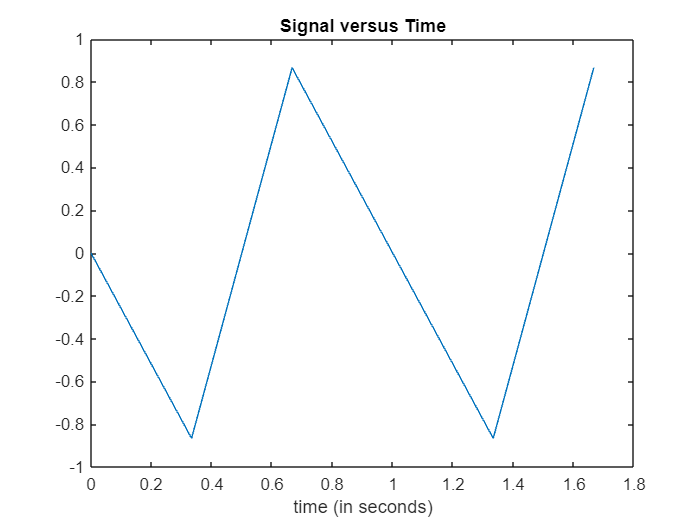

close all

% 1) plot the coriginal sine signal"


   Fs = 3;                   % samples per second
   dt = 1/Fs;                   % seconds per sample
   StopTime = 2;             % seconds
   t = (0:dt:StopTime-dt)';     % seconds
   %%Sine wave:
   Fc = 2;                     % hertz
   x = sin(2*pi*Fc*t);
   % Plot the signal versus time:
   figure;
    plot(t,x);
   xlabel('time (in seconds)');
   title('Signal versus Time');

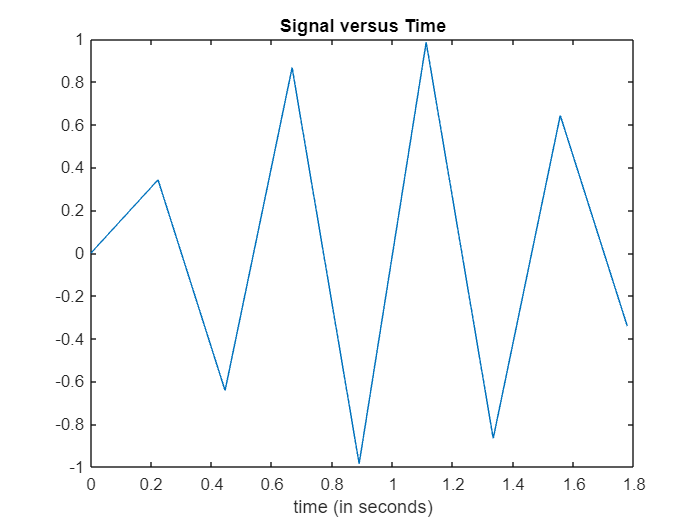

% 2) plot “the original signal with Aliasing” (whose frequency is 1.5 times the highest frequency of the original signal);

 Fs = 3*1.5;                   % samples per second
   dt = 1/Fs;                   % seconds per sample
   StopTime = 2;             % seconds
   t = (0:dt:StopTime-dt)';     % seconds
   %%Sine wave:
   Fc = 2;                     % sin frequency
   xa = sin(2*pi*Fc*t);
   % Plot the signal versus time:
   figure;
    plot(t,xa);
   xlabel('time (in seconds)');
   title('Signal versus Time');

%3) let's consider the discrete Fourier transform of the original signal.

xft = fft(x,4)

xft =    0.0000 + 0.0000i
  -0.8660 + 0.8660i
   1.7321 + 0.0000i
  -0.8660 - 0.8660i


xdft = fft(xft,4)

xdft =          0
   -0.0000
    3.4641
   -3.4641


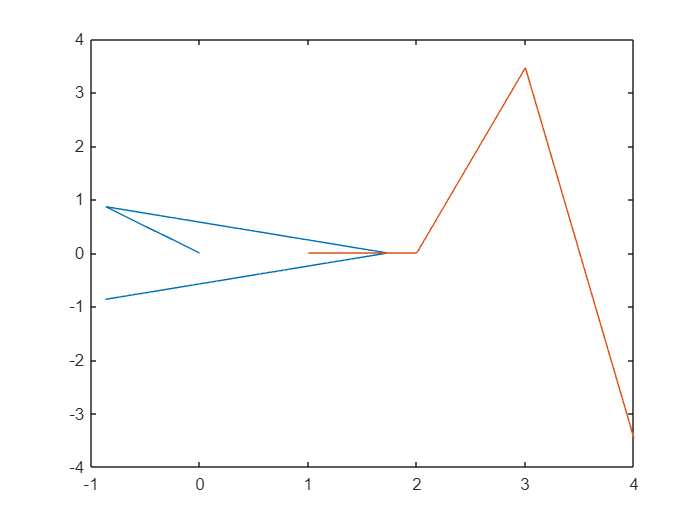

plot(xft)
hold on
plot(xdft)

**Exercise 4: ** 

Using the data in the file 'gc-data-2.txt' 1) find lines that match certain patterns to identify the regions that are data, then we read in the data lines. 2) get the number of data points, and read up to the data; 3) initialize the data vectors and then read in the data; 4) plot the data and then correct for non-zero baseline 5) The plotted peaks are asymmetric, implement a fitting procedure using a decaying gaussian function 6) Implement a fitting procedure with two peaks (to get two peaks, you simply add two peaks together following the steps in point 5) 7) Plot fitting function with an initial guess for each parameter 8) use nonlinear fitting to get the parameters that best fit our data, and plot the fit on the graph 9) now extract out the two peaks and integrate the areas 10) Compute relative amounts.

close all
r= readtable("gc-data-21.txt")

r = 9972×2 table
    R_Time     Intensity
    _______    _________

          0      -288   
    0.00167      -288   
    0.00333      -288   
      0.005      -288   
    0.00667      -320   
    0.00833      -288   
       0.01      -288   
    0.01167      -288   
    0.01333      -288   
      0.015      -288   
    0.01667      -288   
    0.01833      -288   
       0.02      -288   
    0.02167      -320   
    0.02333      -288   
      0.025      -288   


Not enough input arguments.

Error in baseline2TimeShift

r_time = r.R_Time;
int = r.Intensity;

plot(r_time,int)
axis()
hold on




% implement a fitting procedure using a decaying gaussian function

fitrgp(r)






